**Setup**

clc; clear; close all;

% 10 amostras por ciclo
N = 64;
freq=60;
Vi_mag = 155.563;
Vi_fase = 0;
periodo = 1/freq;

% intervalo de amostragem
dt = periodo/N

dt = 2.6042e-04


% elementos do circuito equivalente
R1 = 1;
R2 = 1;
L1 = 2e-6;
L2 = 10e-3;
Z1 = R1 + L1*(1i*2*pi*freq);
Z2 = R2 + L2*(1i*2*pi*freq);
Zeq = Z1 + Z2

Zeq = 2.0000 + 3.7707i


% Criacao do vetor de tempo discreto "n" e "t"
n = zeros(1,N);
t = zeros(1,N);

% Criacao do vetor do sinal de tensao instantanea
%Tensao = zeros(1,N);
%Corrente = zeros(1,N);
%Pot_inst = zeros(1,N);

% Variaveis para armazenar o valor da tensao RMS, potencia ativa, potencia aparente e FP
Tensao_RMS = 0;
Tensao_RMSVo = 0;
Corrente_RMS = 0;

**Calculo dos parametros**

% Inicializa o vetor de tempo discreto "n" e de tempo continuo "t"
for i=0:1:(N-1)
    n(i+1) = i;
    t(i+1) = n(i+1)*dt;
end

% Cria o vetor de um ciclo do sinal de tensao instantanea
Tensao = Vi_mag*sin(2*pi*freq*t+Vi_fase);
stairs(t,Tensao,"k");

hold on
grid on;

% Calcula a corrente instantânea usando a Lei de Ohm
Corrente = Tensao / Zeq;

% Calcula a tensão Vo
Vo = Corrente * Z2;
stairs(t,Vo,"b");

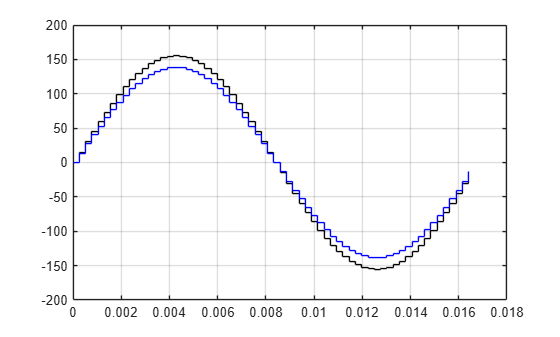

hold off


%stairs(t,Corrente,"r");

**Simulação da Medição das grandezas**

% Calcula o valor RMS do sinal de tensao Vi
for i=0:1:(N-1)
    Tensao_RMS = Tensao_RMS + Tensao(i+1)^2;
end
Tensao_RMS = abs(Tensao_RMS)/N;
Tensao_RMS = sqrt(Tensao_RMS)

Tensao_RMS = 109.9997


% Calcula o valor RMS do sinal de tensao Vo
for i=0:1:(N-1)
    Tensao_RMSVo = Tensao_RMSVo + Vo(i+1)^2;
end
Tensao_RMSVo = abs(Tensao_RMSVo)/N;
Tensao_RMSVo = sqrt(Tensao_RMSVo)

Tensao_RMSVo = 100.5167


% Calcula o valor RMS do sinal de Corrente de malha
for i=0:1:(N-1)
    Corrente_RMS = Corrente_RMS + Corrente(i+1)^2;
end
Corrente_RMS = abs(Corrente_RMS)/N;
Corrente_RMS = sqrt(Corrente_RMS)

Corrente_RMS = 25.7716

**Algoritmo para calcular potências**

% Calcula o valor do fator de potencia por queda de tensão
Fator_De_Potencia = Tensao_RMSVo/Tensao_RMS

Fator_De_Potencia = 0.9138


% Calcula o angulo
angulo = acosd(Fator_De_Potencia)

angulo = 23.9653


% Calcula o valor da pontência aparente 
P_parente_total = Tensao_RMS*Corrente_RMS

P_parente_total = 2.8349e+03


% Calcula o valor da pontência ativa
P_ativa_total = P_parente_total * Fator_De_Potencia

P_ativa_total = 2.5905e+03


% Calcula o valor da pontência reativa
P_reativa_total = P_parente_total * sind(angulo)

P_reativa_total = 1.1515e+03

**Algoritmo para calcular potências da carga**

% Calcula o valor da pontência aparente 
P_parente_carga = Tensao_RMSVo*Corrente_RMS

P_parente_carga = 2.5905e+03


% Calcula o valor da pontência ativa
P_ativa_carga = P_parente_carga * Fator_De_Potencia

P_ativa_carga = 2.3672e+03


% Calcula o valor da pontência reativa
P_reativa_carga = P_parente_carga * sind(angulo)

P_reativa_carga = 1.0522e+03